# Hypotesis Contrasts

mu1=100;
std1=5;
mu2=105;
std2=5;
x = mu1+randn(10,1)*std1;
y = mu2+randn(20,1)*std2;

## Equal average tests

[h, p, ci, stats] = ttest2(x,y)

h = 0

p = 0.1217

ci =    -5.7339
    0.7118


stats = struct with fields:
    tstat: -1.5960
       df: 28
       sd: 4.0624



[h, p, ci, stats] = ttest2(x,y,'Tail','right')

h = 0

p = 0.9391

ci =    -5.1876
       Inf


stats = struct with fields:
    tstat: -1.5960
       df: 28
       sd: 4.0624



[h, p, ci, stats] = ttest2(x,y,'Tail','left')

h = 0

p = 0.0609

ci =       -Inf
    0.1654


stats = struct with fields:
    tstat: -1.5960
       df: 28
       sd: 4.0624



[h, p, ci, stats] = ttest2(x,y,'Alpha',0.01)

h = 0

p = 0.1217

ci =    -6.8587
    1.8365


stats = struct with fields:
    tstat: -1.5960
       df: 28
       sd: 4.0624


## Welch test

[h, p, ci, stats] = ttest2(x,y,'Vartype','unequal')

h = 0

p = 0.1631

ci =    -6.1632
    1.1410


stats = struct with fields:
    tstat: -1.4681
       df: 14.6996
       sd: [2×1 double]


## Wilcoxon Rank-Sum test

[p, h, stats] = ranksum(x,y)

p = 0.2099

h = logical
   0


stats = struct with fields:
       zval: -1.2538
    ranksum: 126


## ANOVA

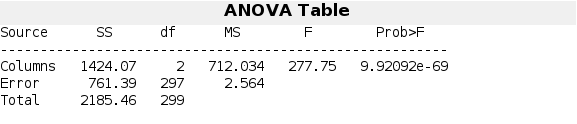

p = 9.9209e-69

tbl = 4×6 cell array
    {'Source' }    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[1.4241e+03]}    {[  2]}    {[712.0340]}    {[277.7478]}    {[9.9209e-69]}
    {'Error'  }    {[  761.3890]}    {[297]}    {[  2.5636]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[2.1855e+03]}    {[299]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: [3×1 char]
         n: [100 100 100]
    source: 'anova1'
     means: [9.9598 8.7748 4.8609]
        df: 297
         s: 1.6011


a=10+randn(100,1)*1;
b=9+randn(100,1)*2;
c=5+randn(100,1)*2;

[p, tbl, stats] = anova1([a b c])

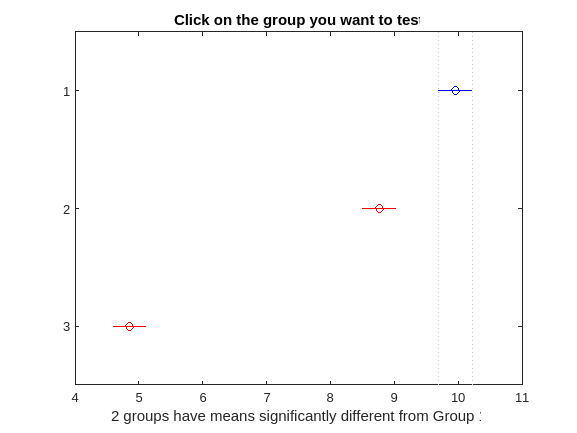

ans =     1.0000    2.0000    0.6543    1.1850    1.7157    0.0000
    1.0000    3.0000    4.5682    5.0989    5.6296         0
    2.0000    3.0000    3.3832    3.9139    4.4446         0



multcompare(stats)